clear all

x_vals = 0:0.1:10;

I_R = 5 - 2./(1+exp(-(x_vals - 2.0)))

I_R =     4.7616    4.7398    4.7163    4.6911    4.6640    4.6351    4.6044    4.5717    4.5370    4.5005    4.4621    4.4219    4.3799    4.3364    4.2913    4.2449    4.1974    4.1489    4.0997    4.0500    4.0000    3.9500    3.9003    3.8511    3.8026    3.7551    3.7087    3.6636    3.6201    3.5781    3.5379    3.4995    3.4630    3.4283    3.3956    3.3649    3.3360    3.3089    3.2837    3.2602    3.2384    3.2182    3.1995    3.1822    3.1663    3.1517    3.1383    3.1259    3.1146    3.1043


%I_P = 3.5 - 3./(1+exp(-2.*(x_vals - 2.0)))
I_P = 3.5 - 2./(1+exp(-2.*(x_vals - 2.0)))

I_P =     3.4640    3.4562    3.4468    3.4354    3.4217    3.4051    3.3854    3.3617    3.3337    3.3005    3.2616    3.2163    3.1640    3.1044    3.0370    2.9621    2.8799    2.7913    2.6974    2.5997    2.5000    2.4003    2.3026    2.2087    2.1201    2.0379    1.9630    1.8956    1.8360    1.7837    1.7384    1.6995    1.6663    1.6383    1.6146    1.5949    1.5783    1.5646    1.5532    1.5438    1.5360    1.5295    1.5243    1.5199    1.5163    1.5134    1.5110    1.5090    1.5074    1.5060


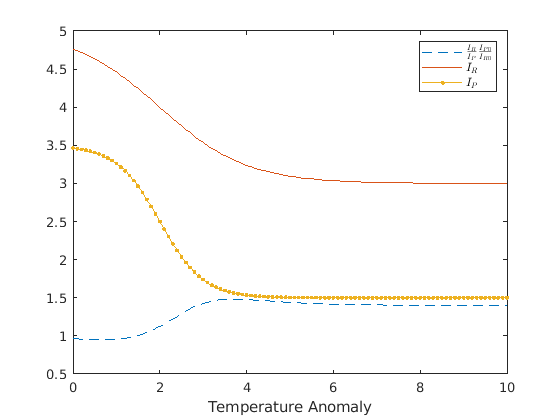

clf
plot(x_vals, (I_R./I_P).*(3.5/5), 'Linestyle', '--' )
hold on
plot(x_vals, I_R)
plot(x_vals, I_P, 'Marker', '.')
xlabel("Temperature Anomaly")
legend('$\frac{I_R}{I_P} \frac{I_{P0}}{I_{R0}}$','$I_R$','$I_P$', 'Interpreter', 'latex')

% dissatisfaction_measure = ( 1.*( (I_R./I_P).*(3.5 ./ 5) );
alpha_P = 4.5.* (1.0./( 1 + exp(-3.*( ( 1.*( (I_R./I_P).*(3.5 ./ 5) )) - 1.5)) ) );

f_T_f = 5 ./ ( 1 + exp(-3.*(x_vals-2.5)) );

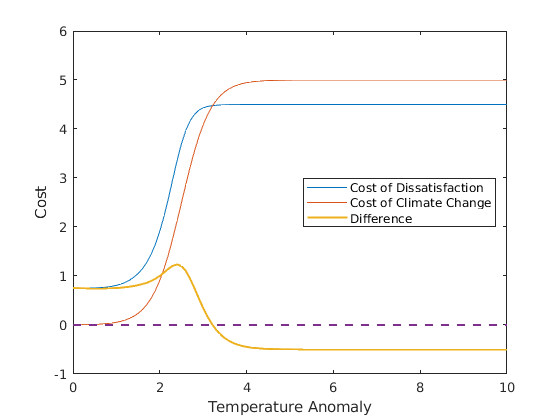

clf
plot(x_vals, alpha_P)
hold on
plot(x_vals, f_T_f)
plot(x_vals, alpha_P - f_T_f, "LineWidth", 1.5)
plot([-1,11],[0,0], "LineStyle", '--', "LineWidth", 1.5)
xlabel("Temperature Anomaly")
ylabel("Cost")
ylim([-1,6])
xlim([0,10])
legend("Cost of Dissatisfaction","Cost of Climate Change", "Difference", "Location", "east")